## **Finite Element Method**

clc; 
clear;
syms x f(x) u_e(x)

a=200

a = 200

b = 0

b = 0

c =0

c = 0

f(x) = x^2

$$f(x) = x^{2}$$




%----------------------------------------------------------------------------
deqn = a*diff(u_e,x,2)+b*diff(u_e,x,1)+c*u_e == f;

Value1 = 0;
Value2 = 1;

ic = u_e(0) == Value1;
d_ue(x)= diff(u_e,x);
%ic2 = d_ue(1) == Value2;
ic2=u_e(1) == Value2;

u_exact = dsolve(deqn,[ic ic2]);
exact_sol_f = u_exact;
%----------------------------------------------------------------------------------


P=1 % Only works till P = 6  % guass points restriction 

P = 1

% P Order of Interpolation Function foe element
ndofel=P+1;

% No of elements
e = 3;

% domain of X
x0 = 0;
xL = 1;
% Element length
h = (xL - x0) / e;




PbarKL1 = 2*P -1

PbarKL1 = 1

PbarKL2 = 2*P

PbarKL2 = 2

PbarKL3 = 3*P

PbarKL3 = 3


% max(PbarKL1,PbarKL2,PbarKL3);

Pbar = PbarKL3

Pbar = 3

if mod(Pbar, 2) == 1 % ODD
    nG = (Pbar + 1) / 2;
else % Even
    nG = (Pbar + 2) / 2;
end
nG 

nG = 2


[w,xi] = GaussQuadrature(nG);

 
shapMatrix=zeros(nG,ndofel);
dshapMatrix=zeros(nG,ndofel);

for i = 1:nG
    xi_loc = xi(i);
    [ndofel,shap,dshap] = SHAPE(P,xi_loc);

    for j =1:ndofel
        shapMatrix(i,j)=shap(j);
        dshapMatrix(i,j)=dshap(j);
    end

end
shapMatrix

shapMatrix =     0.2113    0.7887
    0.7887    0.2113


dshapMatrix

dshapMatrix =    -0.5000    0.5000
   -0.5000    0.5000




%ndofel=P+1;

% Local stiffness matrix
KL1 = zeros(ndofel, ndofel, 'sym');
KL2 = zeros(ndofel, ndofel, 'sym');
KL3_Ten3 = zeros(ndofel, ndofel,ndofel, 'sym');
F_Mat = zeros(ndofel, ndofel, 'sym');

for i = 1:ndofel
    for j = 1:ndofel
        KL1(i, j) = 0;
        KL2(i, j) = 0;
        F_Mat(i, j) =0;
        for k = 1:nG
            KL1(i, j) = KL1(i, j) + (a * dshapMatrix(k,i) *dshapMatrix(k,j)*(2/h)*w(k));
            KL2(i, j) = KL2(i, j) + (-b * dshapMatrix(k,j) * shapMatrix(k,i)*w(k));
    
            F_Mat(i, j) = F_Mat(i, j) + (-1* shapMatrix(k,i)*shapMatrix(k,j)*(h/2)*w(k));
        end
        
    end
end

for i = 1:ndofel
    for j = 1:ndofel
        for K = 1:ndofel
            KL3_Ten3(i, j,K)= 0;
            for M = 1:nG
                KL3_Ten3(i, j, K) =  KL3_Ten3(i, j, K) + (-1* shapMatrix(M,i)*shapMatrix(M,j)*shapMatrix(M,K)*(h/2)*w(M));
            end
        end

    end
end


KL1_sub = KL1;
KL2_sub = KL2;
KL3_Ten3_sub = KL3_Ten3;
F_Mat_sub = F_Mat;

%generl formula for finding size of gloabl stiffness matrix-(S=OIF*e+1
S=P*e+1;

global_matrix_size = S; % each element has 2 nodal points
% Initialize global stiffness matrix

KL1_global = zeros(global_matrix_size);
KL2_global = zeros(global_matrix_size);
KL3_Ten3_global = zeros(global_matrix_size,global_matrix_size,global_matrix_size);
F_global = zeros(global_matrix_size);

% Loop through each element
for element = 1:ndofel-1:S-1

    % Assemble local stiffness matrix into global stiffness matrix
    start_index = element;
    end_index = element + ndofel-1;
    KL1_global(start_index:end_index, start_index:end_index) = KL1_global(start_index:end_index, start_index:end_index) + KL1_sub;
    KL2_global(start_index:end_index, start_index:end_index) = KL2_global(start_index:end_index, start_index:end_index) + KL2_sub;
    KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) = KL3_Ten3_global(start_index:end_index, start_index:end_index,start_index:end_index) + KL3_Ten3_sub;


    F_global(start_index:end_index, start_index:end_index) = F_global(start_index:end_index, start_index:end_index) + F_Mat_sub;
end


X = (x0:h/P:xL)';

c_x = sym(zeros(S, 1));
f_x = sym(zeros(S, 1));

for i = 1:S
    f_x(i) = subs(f, x, X(i));
    c_x(i) = subs(c, x, X(i));
end



% Perform tensor-vector multiplication
KL3_global = zeros(global_matrix_size); % Initialize the result tensor
for i = 1:global_matrix_size

    for j = 1:global_matrix_size

        for k = 1:global_matrix_size

            KL3_global(i, j) = KL3_global(i, j) + KL3_Ten3_global(i, j, k) * c_x(k);
        end
    end
end

%K_global_inverse=InverseTDMA(K_global)

Fv = F_global*f_x;


K_global_D_bc = KL1_global+KL2_global+KL3_global;


% At x0 
Qf = 0; % f force value
K0 = 0;
Del0 = 0;
u0 = Value1;

% At xL
Pf = Value2;
K1 = 0;
Del1 = 0;
%uL = Value2;

Gv = sym(zeros(S, 1));
Sv = sym(zeros(S, 1));
Gv(1) = -Qf;
Sv(1) = -K0*Del0;

Gv(end) = Pf;
Sv(end) = K1*Del1;

K_global_D_bc(1,1) = K_global_D_bc(1,1)-K0;
K_global_D_bc(end,end) = K_global_D_bc(end,end)-K1;


RHS = Fv + Gv + Sv;


% Check if A is specified as a number
if exist('u0', 'var') && isnumeric(u0)
    K_global_D_bc(1,:)= [1,zeros(1, S-1)];  %u0 = 0
    RHS(1) = u0;  % RHS of equation
end

if exist('uL', 'var') && isnumeric(uL)
    K_global_D_bc(end,:)= [zeros(1, S-1), 1];  %un=-1
    RHS(end) = uL;  % RHS of equation
end  


%The Solution of Dirichlet B.C. using FEM is =
u_D_bc = double(K_global_D_bc\RHS);% u at nodal points
disp("-------------------------------------------------------------")

-------------------------------------------------------------


disp("The Solution of Dirichlet B.C. using FEM is")

The Solution of Dirichlet B.C. using FEM is


myTable = table(X, u_D_bc, 'VariableNames', {'Nodal point', 'u'});
disp(myTable);

    Nodal point        u    
    ___________    _________

            0              0
      0.33333      0.0010905
      0.66667      0.0022634
            1      0.0037037



disp("-------------------------------------------------------------")

-------------------------------------------------------------


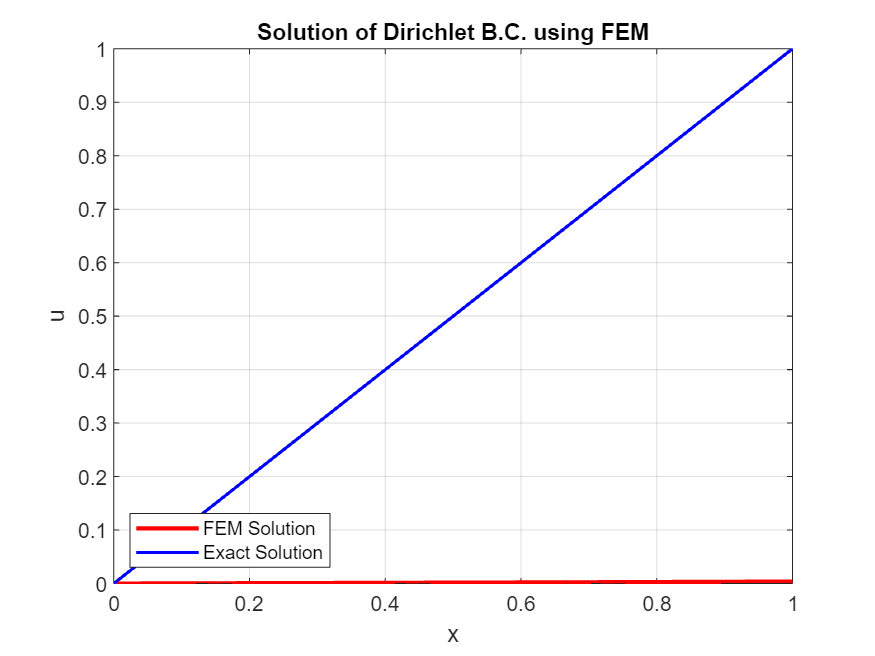

%Plot the FDM Solution and the actual solution
figure;
plot(X, u_D_bc, "r", "LineWidth", 2, "DisplayName", "FEM Solution"); 
hold on;
fplot(x, exact_sol_f, [x0 xL], "b", "LineWidth", 1.5, "DisplayName", "Exact Solution");
xlabel("x");
ylabel("u");
title("Solution of Dirichlet B.C. using FEM");
legend('Location', 'southwest');
grid on;